# Elaborato equazioni differenziali ordinarie.

Di seguito si risolve il sistema di equazioni differenziali, definite nel file *SIR.m. *Le soluzioni sono ottenute considerando diversi valori del paramentro a. Si dimostra, tramite i grafici, come le soluzioni delle equazioni variano sostanzialmente al variare del parametro a. Inoltre viene calcolato il picco dell'epidemia ovvero la coppia di valori (x,y) per cui il numero di persone infette è massimo.

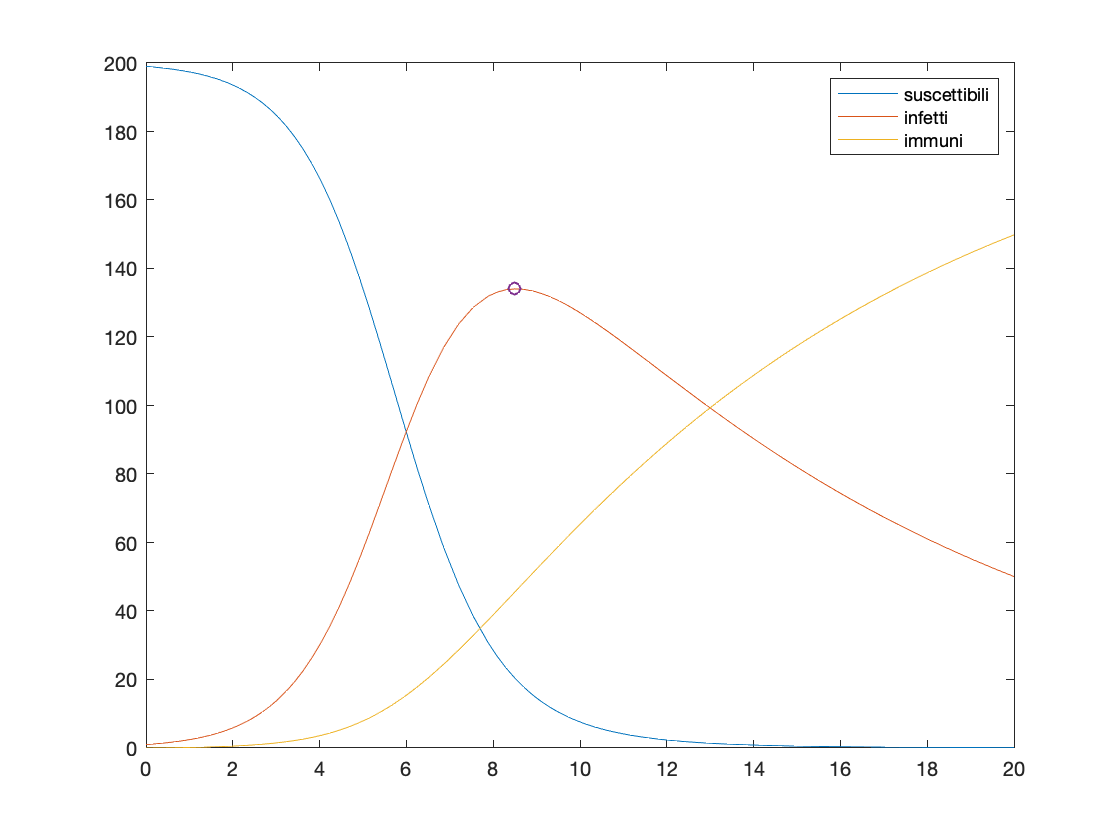

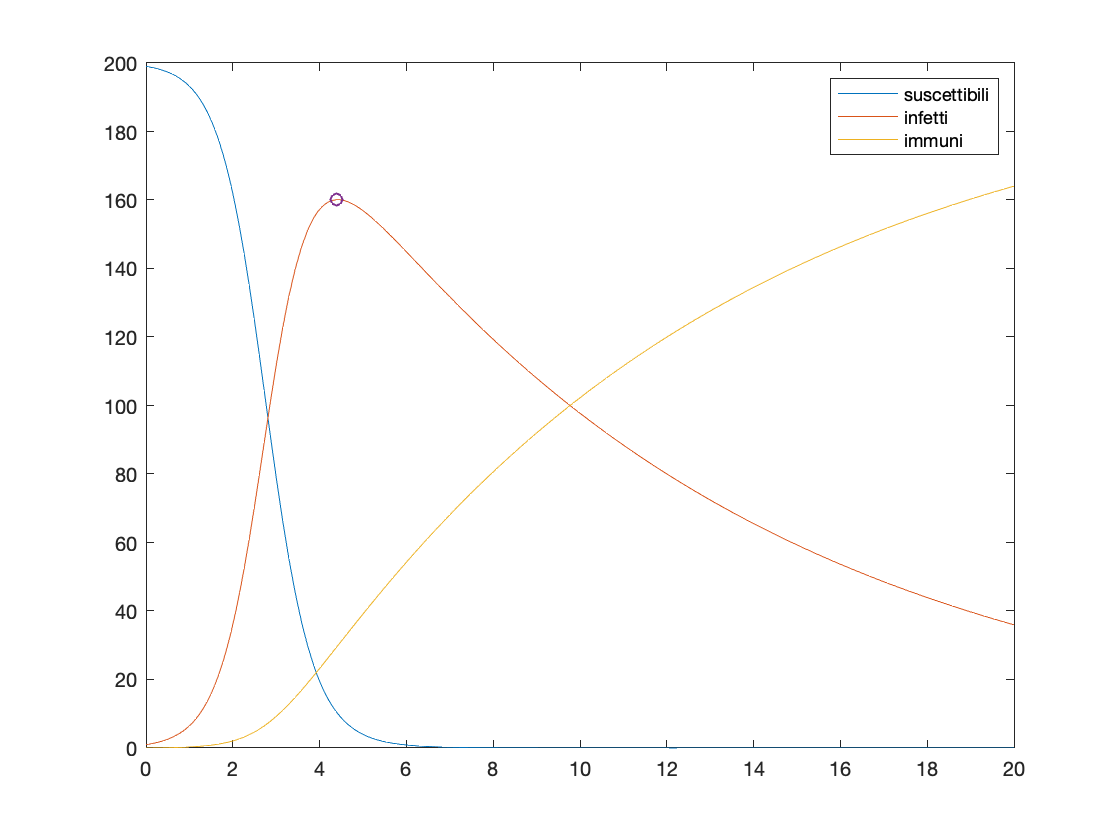

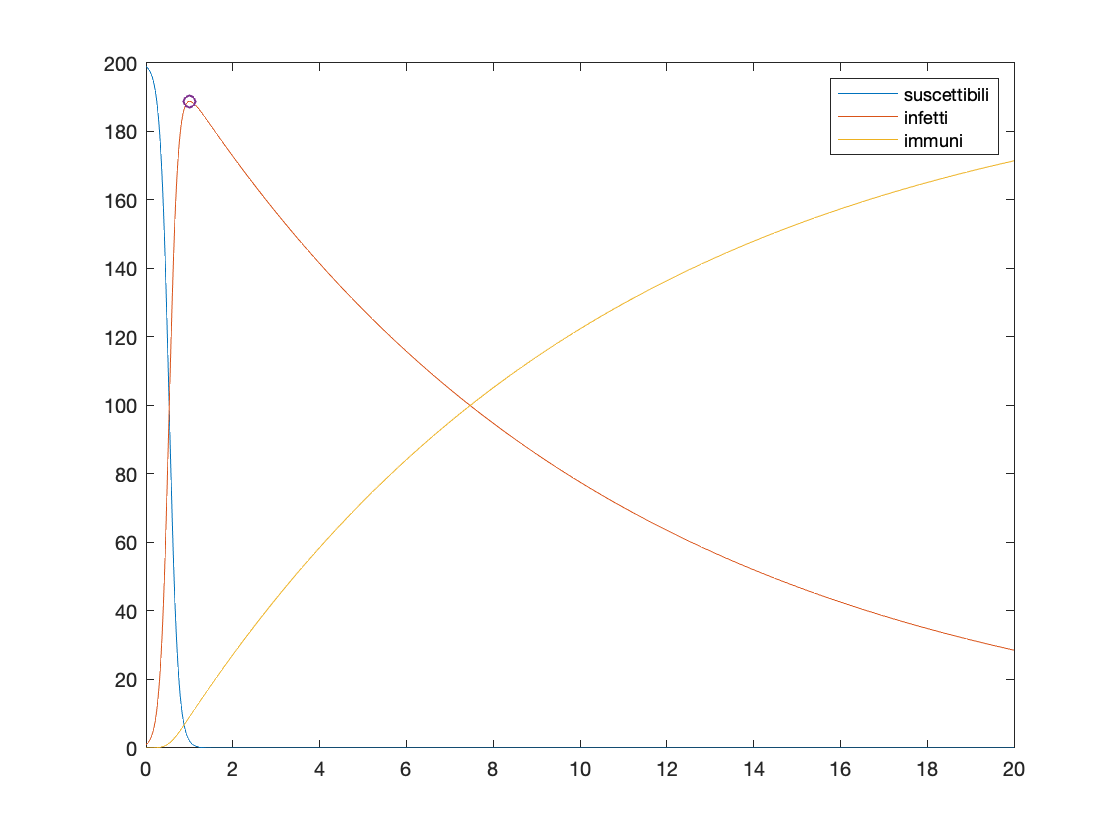

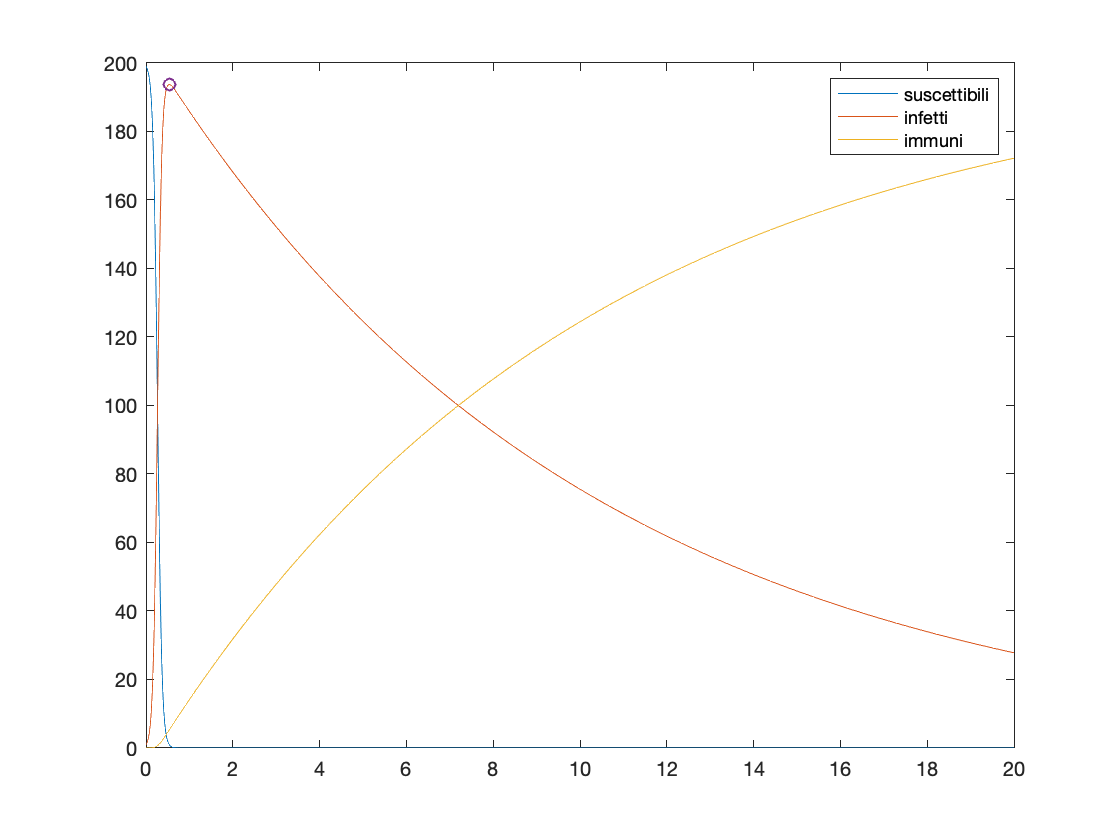

y0 = [199;1;0];
opt=odeset('RelTol',1e-4);
a = [0.005;0.01;0.05;0.1];

for i = 1:length(a)
    [t, x] = ode45(@SIR,[0 20],y0,opt,a(i));
    picco=max(x(:,2));
    tpicco=t(x(:,2)==picco);
    figure('Name',['ode con a = ' num2str(a(i),5),'.']);
    plot(t,x(:,1),t,x(:,2),t,x(:,3),tpicco, picco, "o"); legend("suscettibili", "infetti" , "immuni");
end